clc
clear
close all

## Defining the function:

syms  x t u real
lambda=-145;
f = lambda*x;

matlabFunction(f, 'file', 'Testfn','vars',{x,u});
clear x t f

## Defining r and dr

K = sym('K',[2,1],'real');
syms xk dt real;
A= [0.25 0.25-(sqrt(3)/6);0.25+(sqrt(3)/6) 1/4];
b1= [0.5 0.5];
tFinal=1;
s=2;

for i = 1:s
    r(i,:) = subs(Testfn(xk+dt*(A(i,1)*K(1)+A(i,2)*K(2)),u)- K(i));
end
dr = jacobian(r,K);
matlabFunction(r, dr, 'file', 'rFileIRK4','Vars',{K,xk,dt});
clear K x t dt r dr

## Simulation:

Simulate using IRK4

tFinal = 1;
dt = 0.1;
Nsteps = tFinal/dt;

x0=[1;1];
tIRK4=zeros(Nsteps,1);

x = [x0(1);zeros(Nsteps,1)];
K = x0;

% Loop for the Implicit RK4
for k = 1:Nsteps
    % Newton iteration
    iter = true;
    alpha = 1;
    niter = 0;
    while iter
        tIRK4(k+1)  = tIRK4(k) + dt;
        
        [r,dr] = rFileIRK4(K,x(k),dt); 
        K = K - dr\r;
        norm(r);

        if norm(r) < 1e-5
            iter = false;
        else
            niter = niter + 1;
        end
    end
    K=reshape(K,[s  ,1]);
    x(k+1,:) = x(k)+dt*(b1(1)*K(1)+b1(2)*K(2));
end
xIRK4=x;

Simulate using ERK4

f1 = @(t,x2)lambda*x2;
x0 = 1;
tExact = 0:0.01:tFinal;
xExact = x0*exp(lambda*tExact);

ButcherRK4=butchert(4);
a21=ButcherRK4(2,2);
a32=ButcherRK4(3,3);
a43=ButcherRK4(4,4);
c2=ButcherRK4(2,1);
b2=ButcherRK4(5,2:end)';

nRK4=tFinal/dt;
tERK4 = zeros(nRK4,1);
xERK4 = zeros(nRK4,1);
xERK4(1) = x0;

for j=2: nRK4
    tERK4(j) = tERK4(j-1)+dt; 
    K1 = f1(lambda, xERK4(j-1));
    K2 = f1(lambda, xERK4(j-1)+a21*dt*K1);
    K3 = f1(lambda, xERK4(j-1)+a32*dt*K2);
    K4 = f1(lambda, xERK4(j-1)+a43*dt*K3);
    xERK4(j) = xERK4(j-1) + dt*(b2(1)*K1+ b2(2)*K2+b2(3)*K3+b2(4)*K4);
end

Plotting

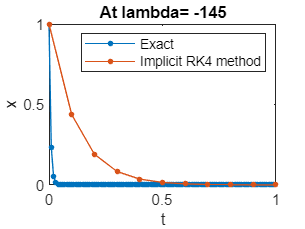

plot(tExact,xExact,'marker','.','markersize',10);
hold on
plot(tIRK4,xIRK4,'marker','.','markersize',10);
%plot(tERK4,xERK4,'marker','.','markersize',10);
title(['At lambda= ',num2str(lambda)])
xlabel('t');
ylabel('x');
legend('Exact','Implicit RK4 method','Explicit RK4 Method')